clear
syms R K s t X(s) x(t) k m b G(s) n d tau

K = 50

K = 50

G = K/(s+50)

$$G = \frac{50}{s+50}$$

[n, d] = numden(G)

$$n = 50$$

$$d = s+50$$

num = flip(coeffs(n,s))

$$num = 50$$

den = flip(coeffs(d,s))

$$den = \left(\begin{array}{cc} 1 & 50 \end{array}\right)$$

[A, B, C, D] = tf2ss(num,den)

$$A = -50$$

$$B = 1$$

$$C = 50$$

$$D = 0$$

Phi = inv(s*eye(1)-A)

$$Phi = \frac{1}{s+50}$$

G1 = C*Phi*B+D

$$G1 = \frac{50}{s+50}$$

[n1, d1] = numden(G1)

$$n1 = 50$$

$$d1 = s+50$$

num1 = flip(coeffs(n1,s))

$$num1 = 50$$

den1 = flip(coeffs(d1,s))

$$den1 = \left(\begin{array}{cc} 1 & 50 \end{array}\right)$$


[A1, B1, C1, D1] = tf2ss(num1,den1)

$$A1 = -50$$

$$B1 = 1$$

$$C1 = 50$$

$$D1 = 0$$

Phi1 = inv(s*eye(1)-A)

$$Phi1 = \frac{1}{s+50}$$

Phi1t = ilaplace(Phi1,s,t)

$$Phi1t = {\mathrm{e}}^{-50\,t}$$

x0 = [0]

x0 = 0

Phi1t_tau = subs(Phi1t,t,t-tau)

$$Phi1t\_tau = {\mathrm{e}}^{50\,\tau -50\,t}$$

x = Phi1t*x0 + int(Phi1t_tau*B,tau,0,t)

$$x = \frac{1}{50}-\frac{{\mathrm{e}}^{-50\,t}}{50}$$

y = C*x

$$y = 1-{\mathrm{e}}^{-50\,t}$$

t_ = [0:0.1:10]

t_ =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


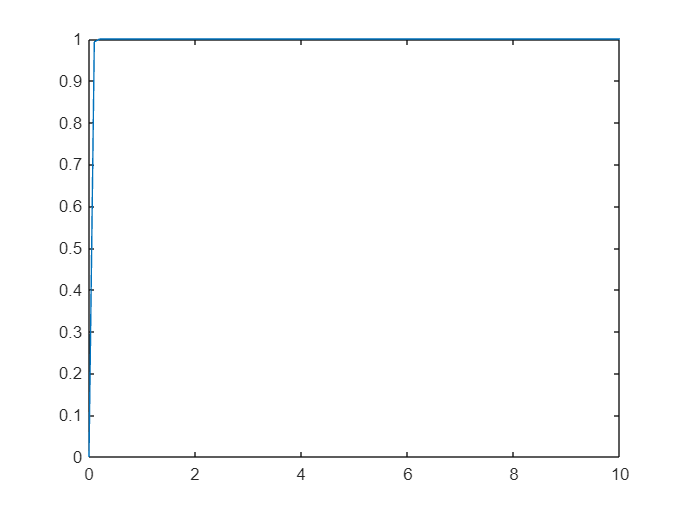

plot(t_,subs(y,t,t_))